# Linear Regression in Matlab

### Assumptions in Linear Regression

- **Linear relationship.**It is also important to check for outliers since linear regression is sensitive to outlier effects. The linearity assumption can best be tested with scatter plots.

- **Multivariate normality.**This assumption can best be checked with a histogram or a Q-Q-Plot. Normality can be checked with a goodness of fit test, e.g., the Kolmogorov-Smirnov test. When the data is not normally distributed a non-linear transformation.

- **No or little multicollinearity.**Multicollinearity occurs when the independent variables are too highly correlated with each other.

- No auto-correlation

- Homoscedasticity (static variance)

load accidents
x = hwydata(:,14); %Population of states
y = hwydata(:,4); %Accidents per state
format long
b1 = x\y

b1 =      1.372716735564871e-04


`b1` is the slope or regression coefficient. The linear relation is *y*=*β*1*x*=0.0001372*x*

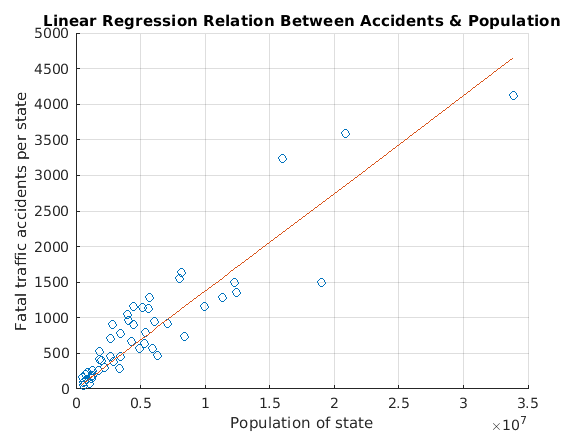

yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('Population of state')
ylabel('Fatal traffic accidents per state')
title('Linear Regression Relation Between Accidents & Population')
grid on

Improve the fit by including a y-intercept *β*0 in your model as *y*=*β*0+*β*1*x*. Calculate *β*0 by padding `x` with a column of ones and using the `\` operator.

X = [ones(length(x),1) x];
b = X\y

b = 	1.0e+02 *

   1.427120171726538
   0.000001256394274


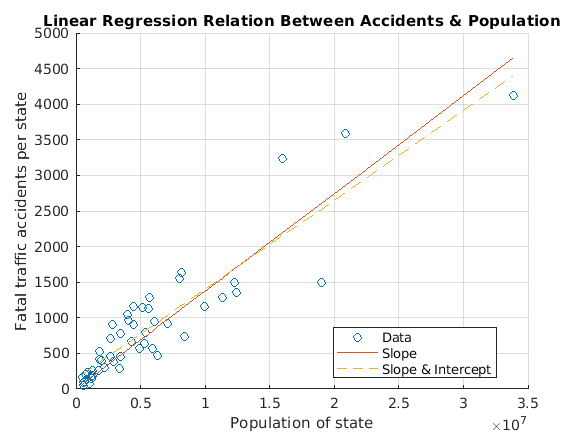

yCalc2 = X*b;
plot(x,yCalc2,'--')
legend('Data','Slope','Slope & Intercept','Location','best');

Rsq1 = 1 - sum((y - yCalc1).^2)/sum((y - mean(y)).^2)

Rsq1 =    0.822235650485566


Rsq2 = 1 - sum((y - yCalc2).^2)/sum((y - mean(y)).^2)

Rsq2 =    0.838210531103428
